## Assigment-Q2

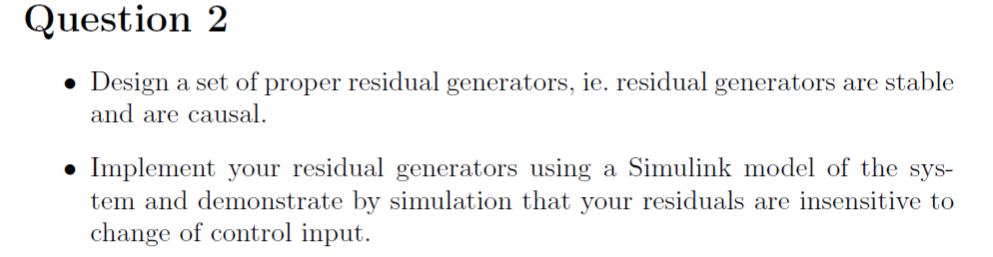


clear all;
close all;
clc;
load('ECP_values.mat');
load('test1.mat','u','meas_fault')

% Physical system parameters
J_1 = 0.0025;                   % Disk 1 inertia kgm^2
J_2 = 0.0018;                   % Disk 2 inertia kgm^2
J_3 = 0.0018;                   % Disk 3 inertia kgm^2
k_1 = 2.7;                      % Shaft 1-2 stiffness Nm/rad
k_2 = 2.6;                      % Shaft 2-3 stiffness Nm/rad
b_1 = 0.0029;                   % Disk 1 damping and friction Nms/rad
b_2 = 0.0002;                   % Disk 2 damping and friction Nms/rad
b_3 = 0.00015;                  % Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s


%Filter parameters for the residuals:
wn=1;                           %natural frequency
zeta=0.96;                      %damping

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions

T_s = 0.004;                    % Sampling period
sigma_meas = deg2rad(0.0056)*[1;1;1]; % Measurements noise

%% GLR
f_m = [0;-0.125;0]; % Sensor fault vector (added to [y1;y2;y3])

%% State space representation

C = [1 0 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 0 1 0];

% Simulation
simTime = 700;       % Simulation duration in seconds
f_m_time = 300;      % Sensor fault occurence time
input_switch=0;

Conclusion:

-Both residuals have first and second order derivatives. Therefore, introduce inestability on the system. To compensate, it is necessary to introduce a filter to each of them, with same order as the second order derivatives.

-H0: No fault presence. "f_y" step is 0. Both residuals have 0 mean value in spite of the disturbances and input that are introduced in the system. Therefore, insensitive of change in control input.

%H0: residual plot

switch_fault=0;
sim('Q2_Simulink');

fig2=figure

fig2 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


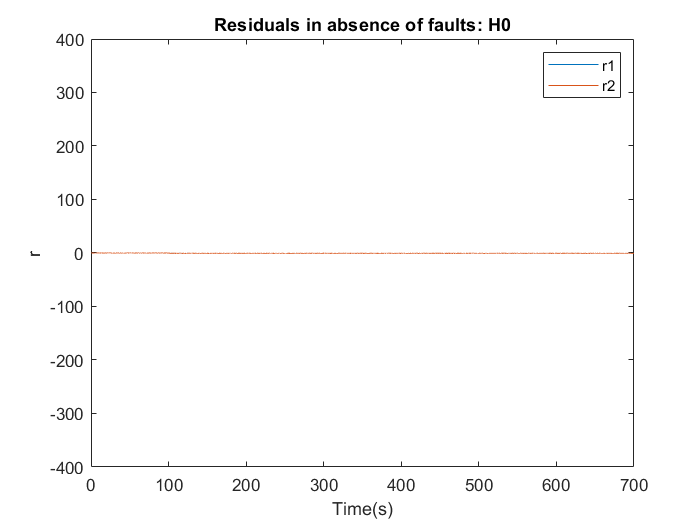

plot(r.time,r.signals.values(:,1),r.time,r.signals.values(:,2))
title('Residuals in absence of faults: H0')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')
ylim([-400 400])
saveas(fig2,'noofault.png')

-H1: Fault presence. "f_y" step is f_m = [0;-0.125;0]; There is a fault in y2. Therefore, residuals change from 0 mean, to non-zero mean value when the faul occurs: f_m_time = 8.5; 

%H1: residual plot

switch_fault=1;
sim('Q2_Simulink');

fig3=figure

fig3 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


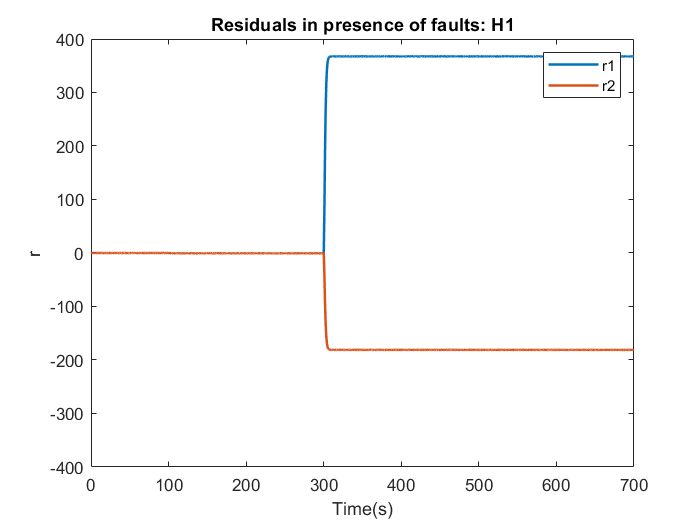

plot(r.time,r.signals.values(:,1),'LineWidth',1.5)
hold on
plot(r.time,r.signals.values(:,2),'LineWidth',1.5)
title('Residuals in presence of faults: H1')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')
ylim([-400 400])
saveas(fig3,'faulty.png')

-The ouput of the system "y" has an unstable response. It makes sense, since the outputs are theta_1,theta_2, theta_3,incremental position encoders for each disc. Input "u" is a torque on the bottom disc that will make the encoders grow unbounded.

%plot output: incremental position encoders

fig1=figure

fig1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


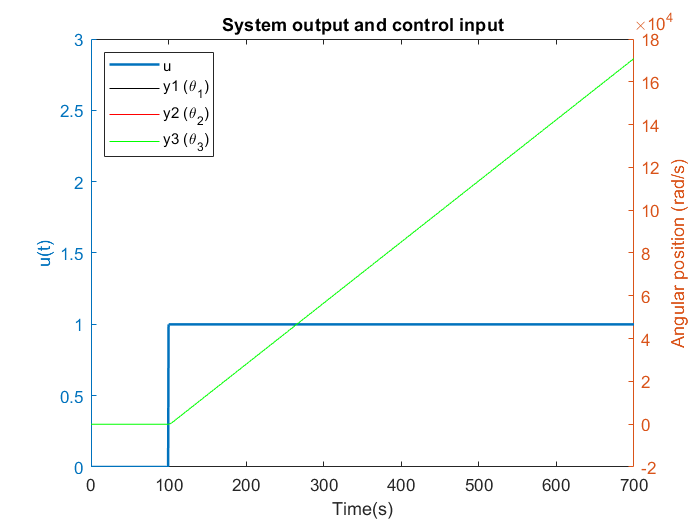

yyaxis left
plot(u1.time,u1.signals.values,'Linewidth',1.5)

ylabel('u(t)')

ylim([0 3])
hold on
yyaxis right
plot(y.time,y.signals.values(:,1),'k',y.time,y.signals.values(:,2),'r-',y.time,y.signals.values(:,3),'g-')
title('System output and control input')
ylabel('Angular position (rad/s)')
xlabel('Time(s)')
legend('u','y1 (\theta_1)','y2 (\theta_2)','y3 (\theta_3)','Location','northwest')
saveas(fig1,'input.png')

input_switch=1;
simTime=17;
f_m_time=8.5;
sim('Q2_Simulink.slx')
fig4=figure

fig4 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


yyaxis left
plot(u1.time,u1.signals.values,'LineWidth',1.5)
ylabel('u(t)')
hold on
yyaxis right
plot(r.time,r.signals.values(:,1),'LineWidth',1.5)
hold on
plot(r.time,r.signals.values(:,2),'k-','LineWidth',1.5)
title('System output and residuals')
ylabel('Residuals')
xlabel('Time(s)')
legend('u','r_1','r_2','Interpeter','Latex','Location','northwest')

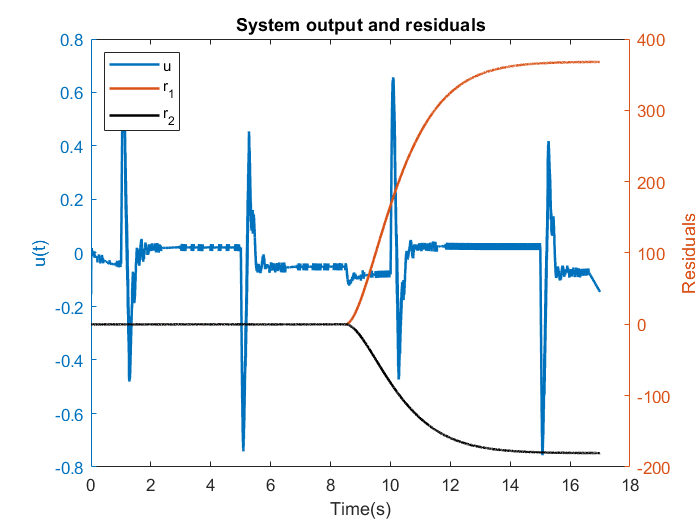

saveas(fig4,'simulation2.png')

$$F = \frac{1}{s^{2}+\frac{48\,s}{25}+1}$$

$$r1 = -\frac{9\,y_{2}\,s^{2}}{5000}+\frac{y_{2}\,s}{5000}+\frac{27\,y_{1}}{10}-\frac{53\,y_{2}}{10}+\frac{13\,y_{3}}{5}$$

$$r2 = -\frac{9\,y_{3}\,s^{2}}{5000}-\frac{3\,y_{3}\,s}{20000}+\frac{13\,y_{2}}{5}-\frac{13\,y_{3}}{5}$$

$$final = \left(\begin{array}{c} \frac{-9\,y_{2}\,s^{2}+y_{2}\,s+13500\,y_{1}-26500\,y_{2}+13000\,y_{3}}{200\,\left(25\,s^{2}+48\,s+25\right)}\\ -\frac{36\,y_{3}\,s^{2}+3\,y_{3}\,s-52000\,y_{2}+52000\,y_{3}}{800\,\left(25\,s^{2}+48\,s+25\right)} \end{array}\right)$$